clc;
clear;
close all hidden;


## load picture

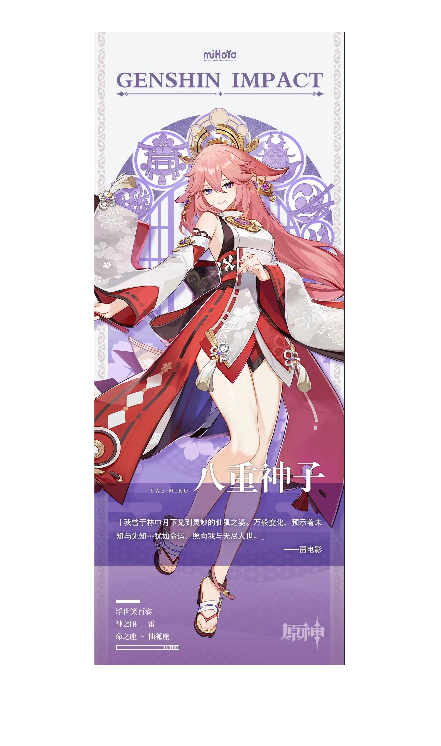

I=imread('KawaKaze.jpg');
I=imread('YaeMiko.jpg');
imshow(I);

I=imresize(I,[64,NaN]);
color_number=3;


## extract picture color

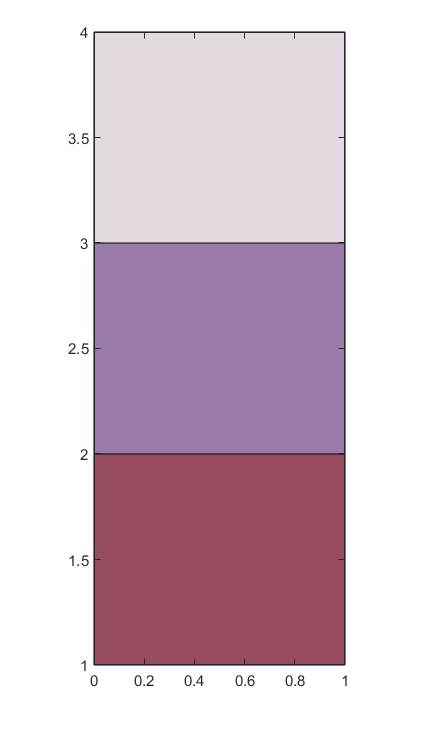

X=I(:,:,1);
Y=I(:,:,2);
Z=I(:,:,3);

color_extract=[X(:),Y(:),Z(:)];

model_MS=clusterFCM(double(color_extract),color_number);
color_extract=(model_MS.center_list)/255;

drawColor(color_extract)

## generate color list

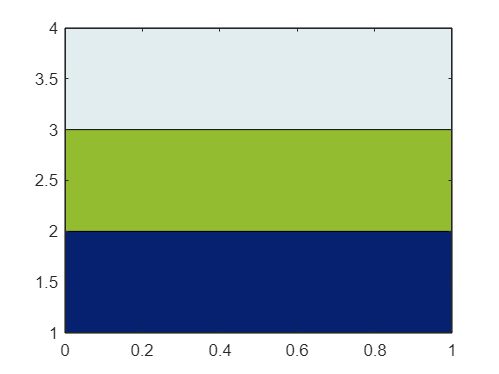

color_extract=[
    6,33,112;
    225,237,239;
    148,188,48]/255;
drawColor(color_extract);

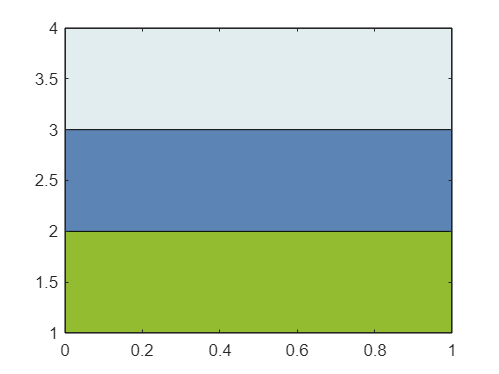

my_color_map=getColorMap(color_extract);

color_extract=[
    92,132,181;
    225,237,239;
    148,188,48]/255;
drawColor(color_extract);

my_color_map_light=getColorMap(color_extract);

save('color','my_color_map','my_color_map_light')


## function

function drawColor(color_list)
[~,idx]=sort(sum(color_list,2));
color_list=color_list(idx,:);

cen_num=size(color_list,1);
for cen_idx=1:cen_num
    X=[0,1,1,0];
    Y=[0,0,1,1]+cen_idx;
    fill(X,Y,color_list(cen_idx,:));
    hold on;
end
hold off;
end

function color_map=getColorMap(color_list)
color_map=[
    [linspace(color_list(1,1),color_list(2,1),101),linspace(color_list(2,1),color_list(3,1),101)];
    [linspace(color_list(1,2),color_list(2,2),101),linspace(color_list(2,2),color_list(3,2),101)];
    [linspace(color_list(1,3),color_list(2,3),101),linspace(color_list(2,3),color_list(3,3),101)];]';
% color_map=uint8(color_map);
end